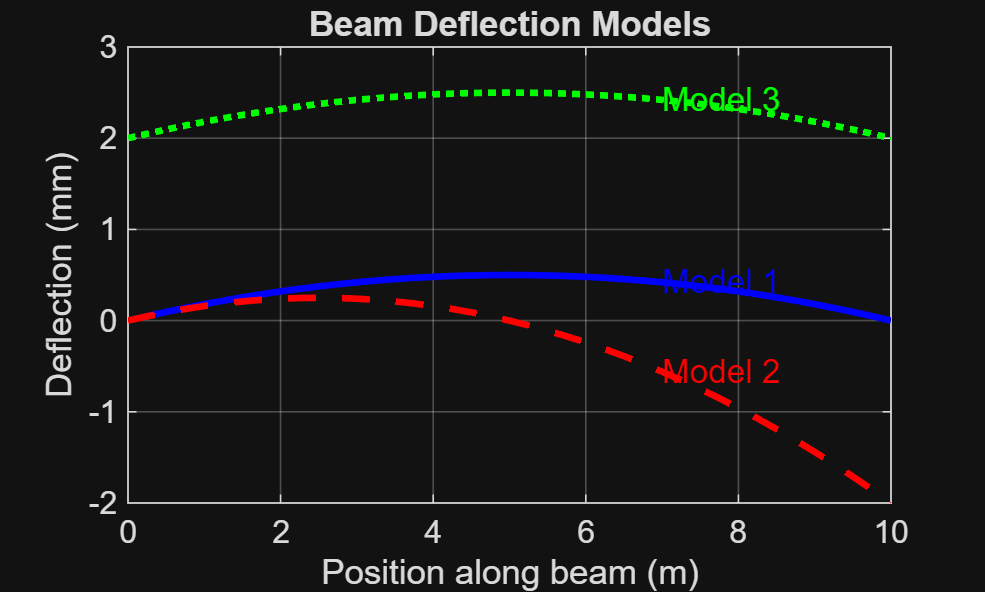

clc; clear; close all;

% Define x range
x = 0:0.25:10;

% Model 1 (baseline)
a1 = -0.02; b1 = 0.2; c1 = 0;
d1 = a1*x.^2 + b1*x + c1;

% Model 2 (change a)
a2 = -0.04; b2 = 0.2; c2 = 0;
d2 = a2*x.^2 + b2*x + c2;

% Model 3 (change c)
a3 = -0.02; b3 = 0.2; c3 = 2;
d3 = a3*x.^2 + b3*x + c3;

% Plot all models
figure;
plot(x, d1, 'b', 'LineWidth', 2); hold on;
plot(x, d2, 'r--', 'LineWidth', 2);
plot(x, d3, 'g:', 'LineWidth', 2);
grid on;

xlabel('Position along beam (m)');
ylabel('Deflection (mm)');
title('Beam Deflection Models');

% Add labels directly on curves
text(7, d1(find(x>=7,1)), 'Model 1', 'Color', 'b');
text(7, d2(find(x>=7,1)), 'Model 2', 'Color', 'r');
text(7, d3(find(x>=7,1)), 'Model 3', 'Color', 'g');


% Find extrema (vertex)
xv1 = -b1/(2*a1);
dv1 = a1*xv1^2 + b1*xv1 + c1;

xv2 = -b2/(2*a2);
dv2 = a2*xv2^2 + b2*xv2 + c2;

xv3 = -b3/(2*a3);
dv3 = a3*xv3^2 + b3*xv3 + c3;

% Display results
fprintf('Model 1 max at x = %.2f m, d = %.2f mm\n', xv1, dv1);

Model 1 max at x = 5.00 m, d = 0.50 mm


fprintf('Model 2 max at x = %.2f m, d = %.2f mm\n', xv2, dv2);

Model 2 max at x = 2.50 m, d = 0.25 mm


fprintf('Model 3 max at x = %.2f m, d = %.2f mm\n', xv3, dv3);

Model 3 max at x = 5.00 m, d = 2.50 mm
